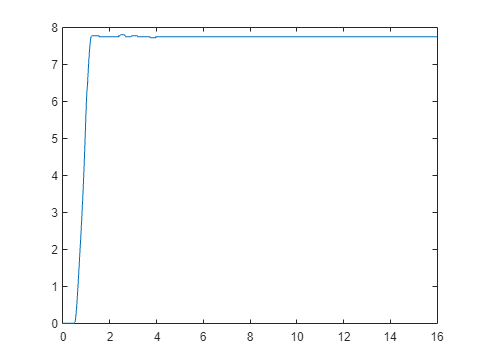

clc; clear; close all;

%load("raw_data\baseAngleVelFilterd.mat")
%temp(1:length(baseAngleVelFilterd.time)) = baseAngleVelFilterd.signals.values( :, :, 1:end);
%baseAngleVelFilterd.signals.values = [];
%baseAngleVelFilterd.signals.values = temp;
%BaseTest.baseAngleVelFilterd = baseAngleVelFilterd;
impulseTest.description = "Impulse test. Impuls after 0.5s. Ampludude =100/255. Duration = 0.5s. Then 15 seconds of rest.";



load("baseAngle.mat");
temp(1:length(baseAngle.time)) = baseAngle.signals.values( :, :, 1:end);
baseAngle.signals.values = [];
baseAngle.signals.values = temp;

load("baseAngleVelFilterd.mat");
temp(1:length(baseAngleVelFilterd.time)) = baseAngleVelFilterd.signals.values( :, :, 1:end);
baseAngleVelFilterd.signals.values = [];
baseAngleVelFilterd.signals.values = temp;

load("baseAngleVelRaw.mat");
temp(1:length(baseAngleVelRaw.time)) = baseAngleVelRaw.signals.values( :, :, 1:end);
baseAngleVelRaw.signals.values = [];
baseAngleVelRaw.signals.values = temp;

load("pendAngle.mat");
temp(1:length(pendAngle.time)) = pendAngle.signals.values( :, :, 1:end);
pendAngle.signals.values = [];
pendAngle.signals.values = temp;

load("voltage.mat");
temp(1:length(voltage.time)) = voltage.signals.values( :, :, 1:end);
voltage.signals.values = [];
voltage.signals.values = temp;

impulseTest.baseAngle = baseAngle;
impulseTest.baseAngleVelFilterd = baseAngleVelFilterd;
impulseTest.baseAngleRaw = baseAngleVelRaw;
impulseTest.pendAngle = pendAngle;
impulseTest.voltage = voltage;

plot(impulseTest.baseAngle.time, impulseTest.baseAngle.signals.values)

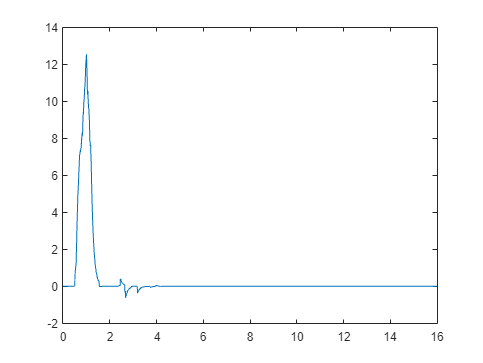

plot(impulseTest.baseAngleVelFilterd.time, impulseTest.baseAngleVelFilterd.signals.values)

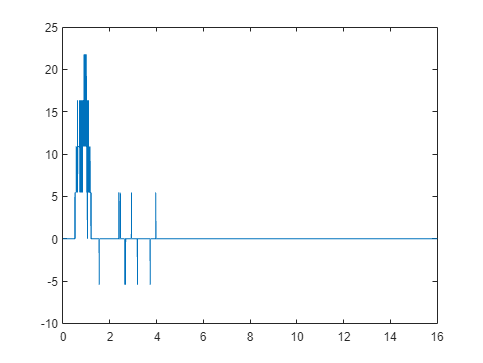

plot(impulseTest.baseAngleRaw.time, impulseTest.baseAngleRaw.signals.values)

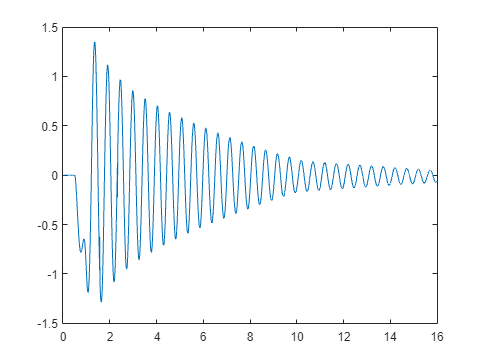

plot(impulseTest.pendAngle.time, impulseTest.pendAngle.signals.values)

plot(impulseTest.voltage.time, impulseTest.voltage.signals.values)

Error using plot
Vectors must be the same length.